# Ray Tracing (Geometric Optics)

This raytracing script works for rays traveling along the x axis. 

## Begin Script

clear all; clc; close all;

## Define General parameters

Refraction indices, space and medium of propagation. 

N = 2.^4; %Definition of simulation

%Space
x = linspace(-10,10,N); 
y = x; 
[X,Y] = meshgrid(x,y);

%Refraction indices
n1 = 0.4;
n2 = 1.82; 

% Medium of propagation
Medium = ones(N,N).* n1;
hh = find(X>=0);
Medium(hh) = n2;

%Number of rays to model
rays = 10; 

Plot the medium of propagation.

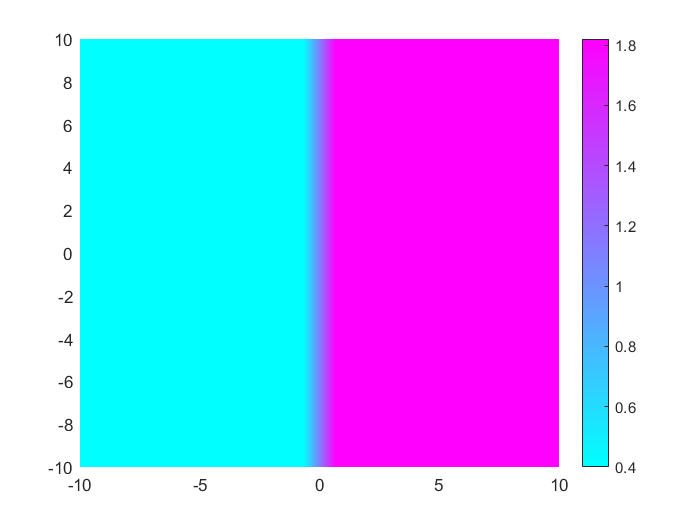

figure
pcolor(x,y,Medium);
shading interp
colormap cool
colorbar
hold on

Model the rays

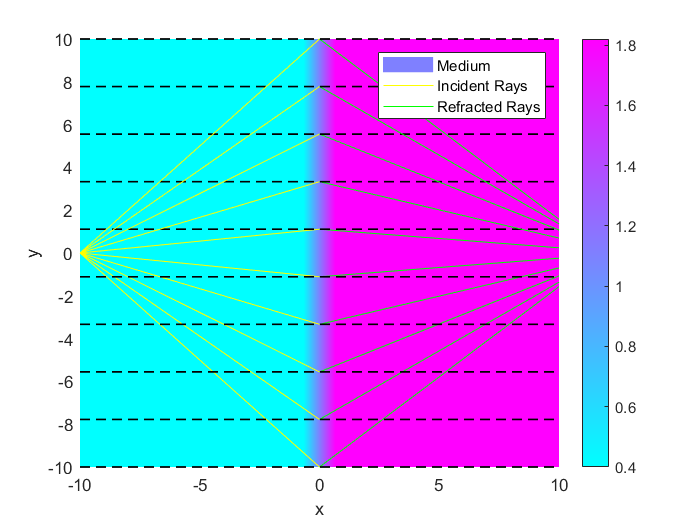

%Prealocate
thetai = zeros(1,rays); % Incident angles
theta2 = zeros(1,rays); % Refracted angles
yf = zeros(1,rays);

x0 = -10; y0 = 0;                           %Start coordinates
xi = 0; yi = linspace(min(y),max(y),rays);  %Incident coordinates
x2 = 10; xf = x2 - xi;                      %Refracted x parameters

for ii = 1:rays
    thetai(ii) = atan((yi(ii)-y0)./(xi-x0));            %Incident angle 
    theta2(ii) = asin(((n1)./(n2)).*sin(thetai(ii)));   %Refracted angle
    yf(ii) = xf .* tan(theta2(ii));                     %Refracted Y coor
    %Plot individual rays
    plot([x0,xi],[y0,yi(ii)],"y")
    hold on
    plot([xi,xf],[yi(ii),yf(ii)],'g')
    hold on
    plot([-10 10],[yi(ii), yi(ii)],'--k','LineWidth',1)
end
%Plot Parameters
legend("Medium","Incident Rays","Refracted Rays")
xlabel("x")
ylabel("y")